# Lab Assignment 8

#### ### Insert Name ###

## Prepare Workspace

close all
clear

load lab8dat.mat


fhat = 1/12

fhat = 0.0833

x = 1 - exp(-1j*2*pi*fhat)

x = 0.1340 + 0.5000i

A = abs(x)

A = 0.5176

phi = angle(x)

phi = 1.3090


x2 = 1 - 2*exp(-1j*(2*pi*fhat + (pi/2)))

x2 = 2.0000 + 1.7321i

A2 = abs(x2)

A2 = 2.6458

phi2 = angle(x2)

phi2 = 0.7137

## Item 3

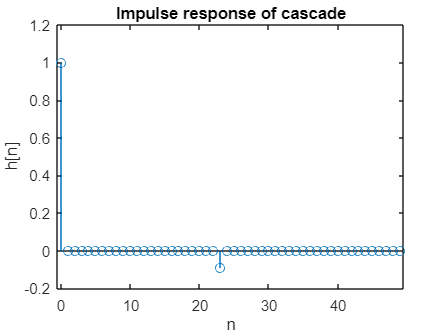


% Complete the following lines and Uncomment to Run
b = [1,-.9]; % <--- complete this line
b_recov =  .9.^[0:22];  % <--- complete this line
h = filter(b_recov,1,[b zeros(1,48)]);% <--- complete this line

figure
stem(0:49,h)
xlabel('n')
ylabel('h[n]')
title('Impulse response of cascade')
xlim([-0.5, 49.5])
ylim([-0.2, 1.2])

## Item 4

% Listen to the original audio
soundsc(x2,8000)

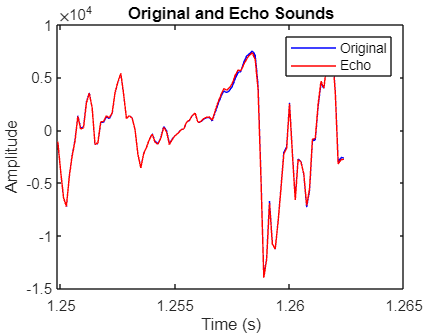

% Apply an echo to the speech signal in x2 and listen to it

% Complete the following lines and Uncomment to Run
b = [ 1 zeros(1,399) 0.05 ]; % <--- complete this line
y2 = filter(b,1,x2);  % <--- complete this line

soundsc(y2,8000)

% Define the time axis
t = (0:length(x2)-1)/8000;

% Plot the original and filtered sounds from sample indices 10000 to 10100
figure;
plot(t(10000:10100), x2(10000:10100), 'b', t(10000:10100), y2(10000:10100), 'r');
xlabel('Time (s)');
ylabel('Amplitude');
legend('Original', 'Echo');
title('Original and Echo Sounds');